**Problem 1**

Part 1a

For additive uncertainty we have $G = G_{nom}+W_A\Delta$.  This implies that $\Delta = \frac{G-G_{nom}}{W_A}$, and the requirement $\|\Delta\|_\infty<1$ requires $|W_A|>|G-G_{nom}|$ $\forall \omega$.  $\Rightarrow |W_A| > |\frac{3e^{-0.1s}-3(0.1s+1)^2}{(2s+1)(0.1s+1)^2}|$ .  Let's build that function and look at its magnitude plot.

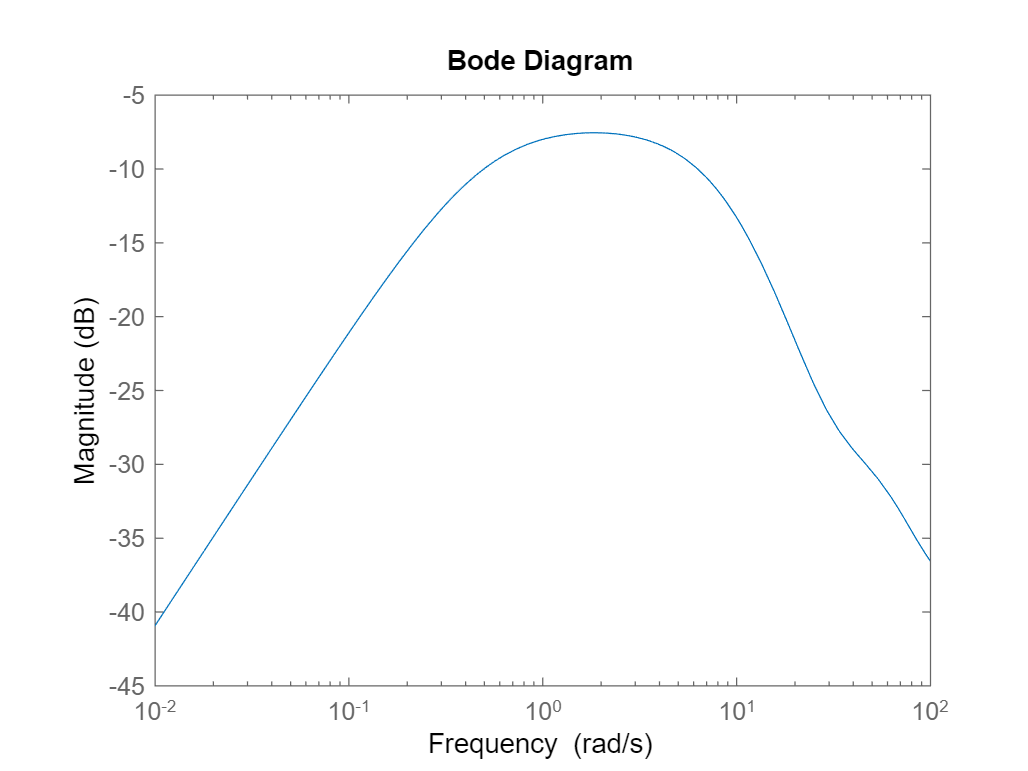

s = tf('s');
WA_min = (3*exp(-0.1*s)-3*(0.1*s+1)^2)/((2*s+1)*(0.1*s+1)^2);
bodemag(WA_min)

We can easily fit a rational function to this via the pade command.

WA_rat = tf(pade(WA_min,1))

WA_rat =
 
   -1.5 s^3 - 60 s^2 - 900 s - 1.498e-13
  ----------------------------------------
  s^4 + 40.5 s^3 + 520 s^2 + 2250 s + 1000
 
Continuous-time transfer function.



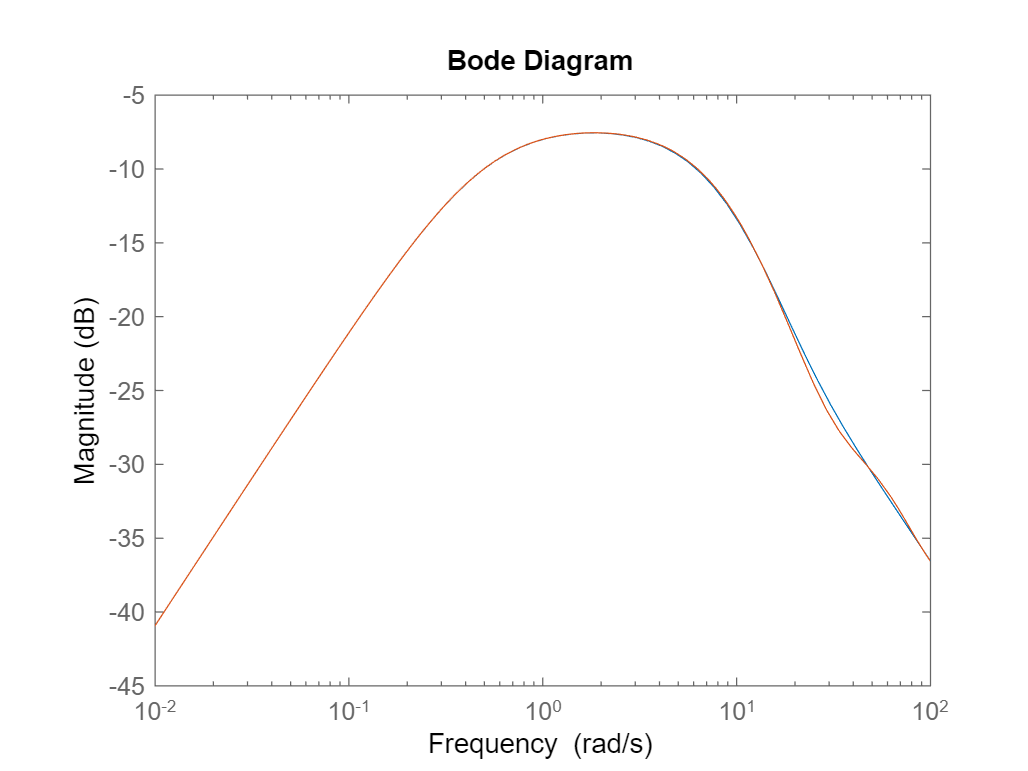

bodemag(WA_rat,WA_min)

Part 1b

This one is very similar to above but we have that $|W_I|>|\frac{G-G_{nom}}{G_{nom}}|=|\frac{\frac{10(-0.5s+1)-10(0.2s+1)(20s+1)}{(6s+1)(0.2s+1)(20s+1)}}{\frac{10}{6s+1}}|=|\frac{(-0.5s+1)-(0.2s+1)(20s+1)}{(0.2s+1)(20s+1)}|$

WI_min = ((-0.5*s+1)-(0.2*s+1)*(20*s+1))/((0.2*s+1)*(20*s+1))

WI_min =
 
   -4 s^2 - 20.7 s
  ------------------
  4 s^2 + 20.2 s + 1
 
Continuous-time transfer function.



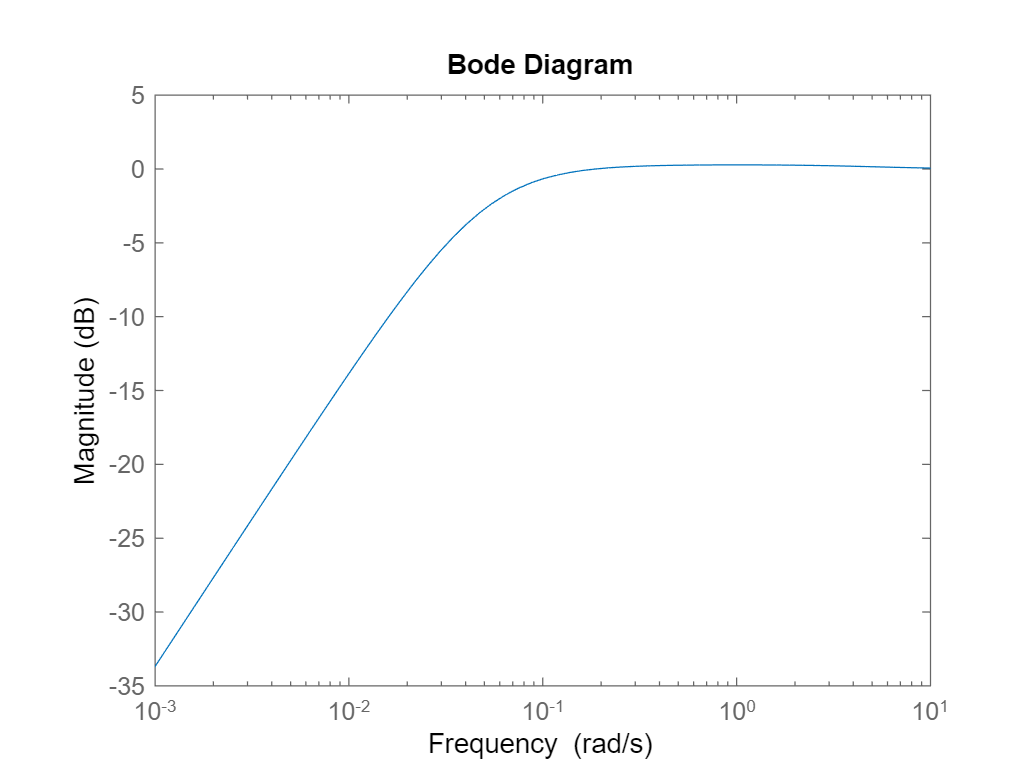

bodemag(WI_min)

Part 1c

This problem is essentially a pattern matching exercise.  We know the form of the uncertain plants and simply need to match them to $G_p = H_{22}+H_{21}\Delta(I-H_{11}\Delta)^{-1}H_{12}$.

1.)  $G_p = G+\Delta_AW_A$:  $H_{22} = G$, $H_{21} = I
$, $H_{11} = 0$, $H_{12} = W_A
$

2.)  $G_p = G(I+\Delta_IW_I)$:  $H_{22} = G$, $H_{21} = G
$, $H_{11} = 0$, $H_{12} = W_I
$

3.)  $G_p = (I+\Delta_OW_O)G$:  $H_{22} = G$, $H_{21} = I
$, $H_{11} = 0$, $H_{12} = W_OG
$

For this below I need to use the trick $(I-ABC)^{-1} =I+ AB(I-CAB)^{-1}C$

4.)  $G_p = G(I-W_{i_A}\Delta_{i_A}G)^{-1}$:   $H_{22} = G
$, $H_{21} =  GW_{i_A}

$, $H_{11} =  GW_{i_A}$, $H_{12} = G
$

5.)  $G_p = G(I-W_{i_I}\Delta_{i_I})^{-1}$:  $H_{22} = G$, $H_{21} = GW_{i_I}
$, $H_{11} = W_{i_I}$, $H_{12} = I
$

6.)  $G_p = (I-W_{i_O}\Delta_{i_O})^{-1}G$:  $H_{22} = G$, $H_{21} = W_{i_O}
$, $H_{11} = W_{i_O}$, $H_{12} = G
$

**Problem 2**

Part 2a

Pull in the plant.

HDDModel_DS_Uncertain;
Gv = VCM.NominalValue;
Gp = PZT.NominalValue;

I'm just going to use *ucover* and accept whatever results it gives.

Gp_samples = usample(PZT,100);
[Pp,info] = ucover(Gp_samples,Gp,2);
W_Dp = tf(info.W1)

W_Dp =
 
  58.8 s^2 + 3.574e06 s + 1.15e08
  -------------------------------
    s^2 + 1.372e04 s + 2.528e09
 
Continuous-time transfer function.



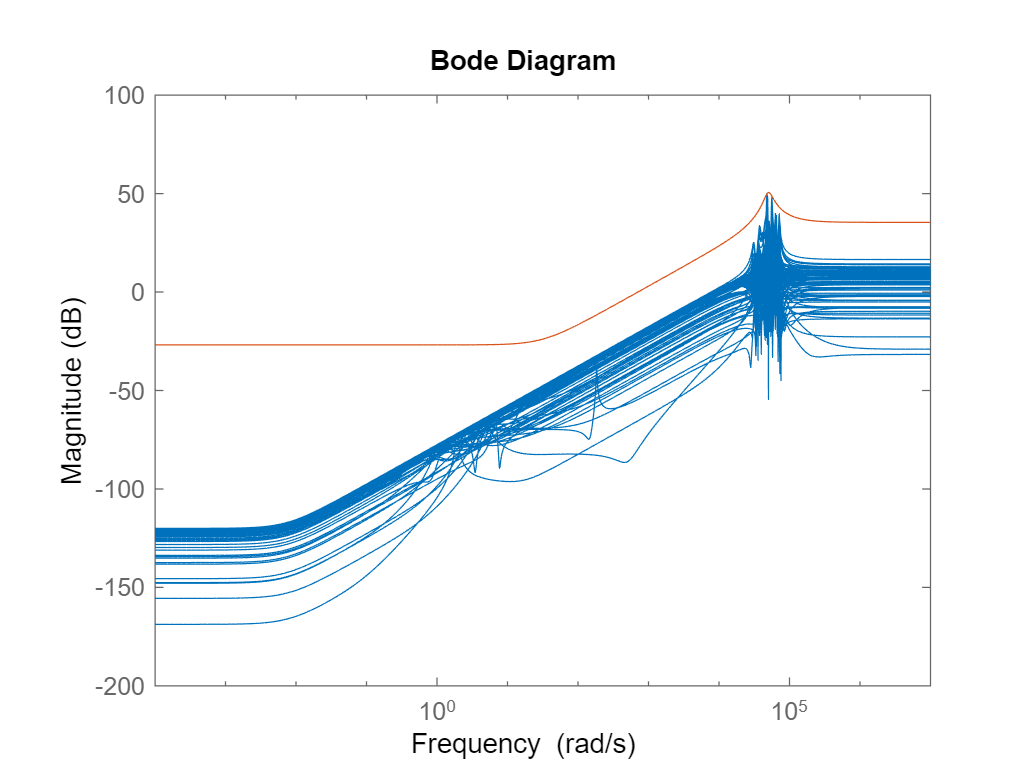

bodemag((Gp_samples-Gp)/Gp,W_Dp);


Gv_samples = usample(VCM,100);
[Pv,info] = ucover(Gv_samples,Gv,2);
W_Dv = tf(info.W1)

W_Dv =
 
  20.09 s^2 + 5.808e06 s + 4.37e08
  --------------------------------
    s^2 + 5.817e04 s + 4.075e09
 
Continuous-time transfer function.



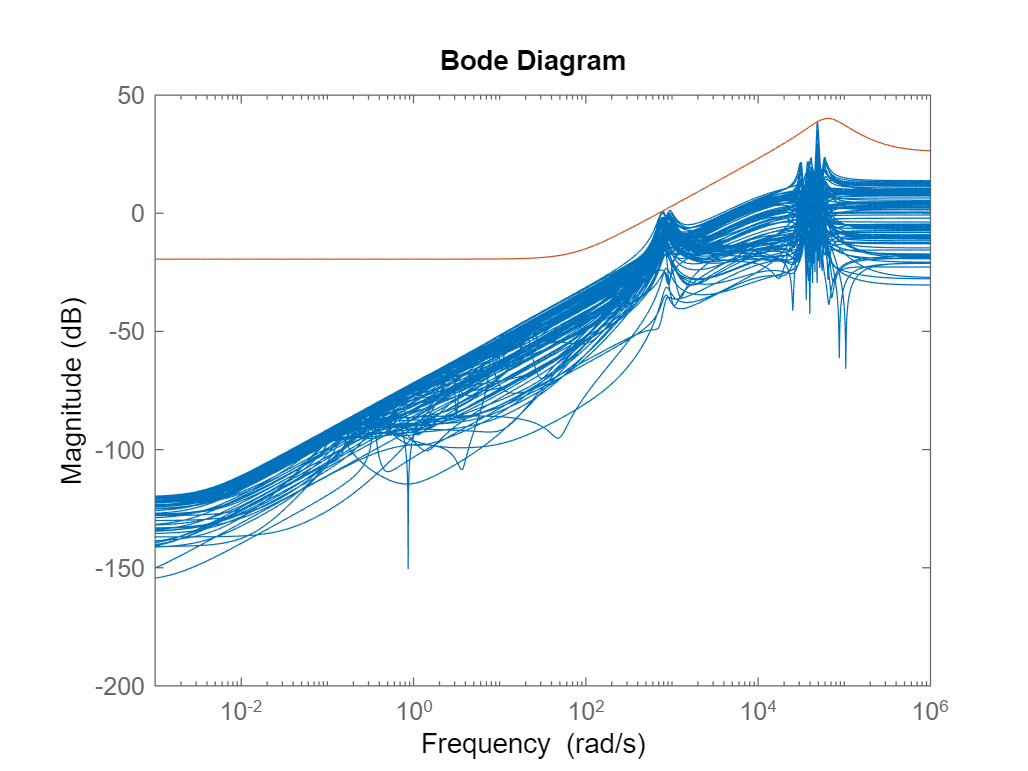

bodemag((Gv_samples-Gv)/Gv,W_Dv,{0.001,1000000});

Part 2b

This solution is based off of the class script "SISO Robust Control".  NOTE:  The results here will vary if you used other, more accurate methods to get your uncertainty weight.

wh = 2000;  %Just guessing at this...we'll see if it fails
wl = 0;
w_try = wh;  %Just for simplicity
w_new = 1/2*(wh+wl);
while(abs(w_new-w_try)>.001)  %Stopping criterion
    w_try = w_new;
    Wp = makeweight(1000,w_try,1/2);
    [K,CL,GAM] = mixsyn(Gv,Wp,[],W_Dv);
    if GAM<1
        wl = w_try;  %We're not agressive enough
    else
        wh = w_try;  %We're too agressive
    end
    w_new = 1/2*(wh+wl);
end
S = 1/(1+Gv*K);
H_inf_norm = norm([Wp*S;W_Dv*(1-S)],'inf')

H_inf_norm = 1.0000

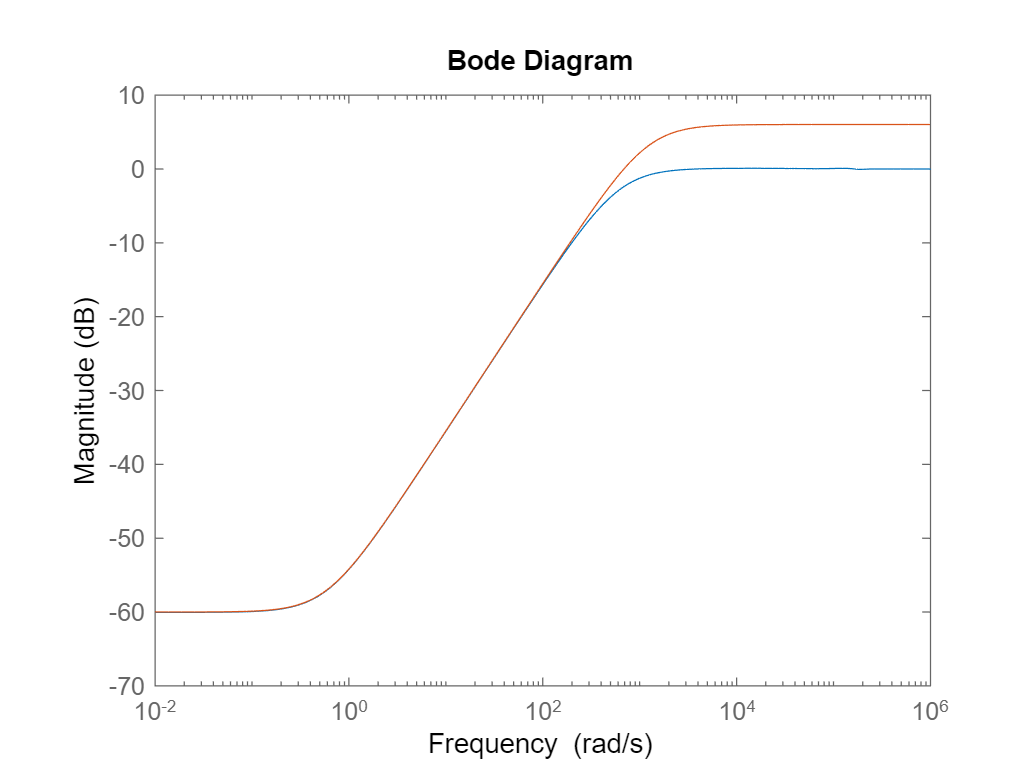

bodemag(S,1/Wp)

Part 2c

This part is very similar to the last, but for the dual-stage system, and I'll use $H_\infty$ synthesis instead of *mixsyn* so I don't have to think about how to handle the different sources of uncertainty in *mixsyn*.

Gnom = [Gv Gp];
Gmult = [Pv Pp];
Gorig = [VCM PZT];
systemnames = 'Gv Gp W_Dv W_Dp Wp';
inputvar = '[ud1;ud2;d;u1;u2]';
outputvar = '[W_Dv;W_Dp;Wp;-Gv-Gp-d]';
input_to_Gv = '[u1+ud1]';
input_to_Gp = '[u2+ud2]';
input_to_W_Dv = '[u1]';
input_to_W_Dp = '[u2]';
input_to_Wp = '[Gv+Gp+d]';
cleanupsysic = 'no';  %This drops all the useless variables from workspace
P = sysic;

Now start the iteration.  Note that the calculation for the original system should 

wh = 1000;  %Just guessing at this...we'll see if it fails
wl = 0;
w_try = wh;  %Just for simplicity
w_new = 1/2*(wh+wl);
gamma = [];
mumult = [];
muorig = [];
while(abs(w_new-w_try)>.001)  %Stopping criterion
    w_try = w_new;
    Wp = makeweight(1000,w_try,1/2);
    P = sysic;
    [K,CL,GAM] = hinfsyn(P,1,2);
    gamma = [gamma GAM];
    if GAM<3.5
        wl = w_try;  %We're not agressive enough
    else
        wh = w_try;  %We're too agressive
    end
    w_new = 1/2*(wh+wl);
end


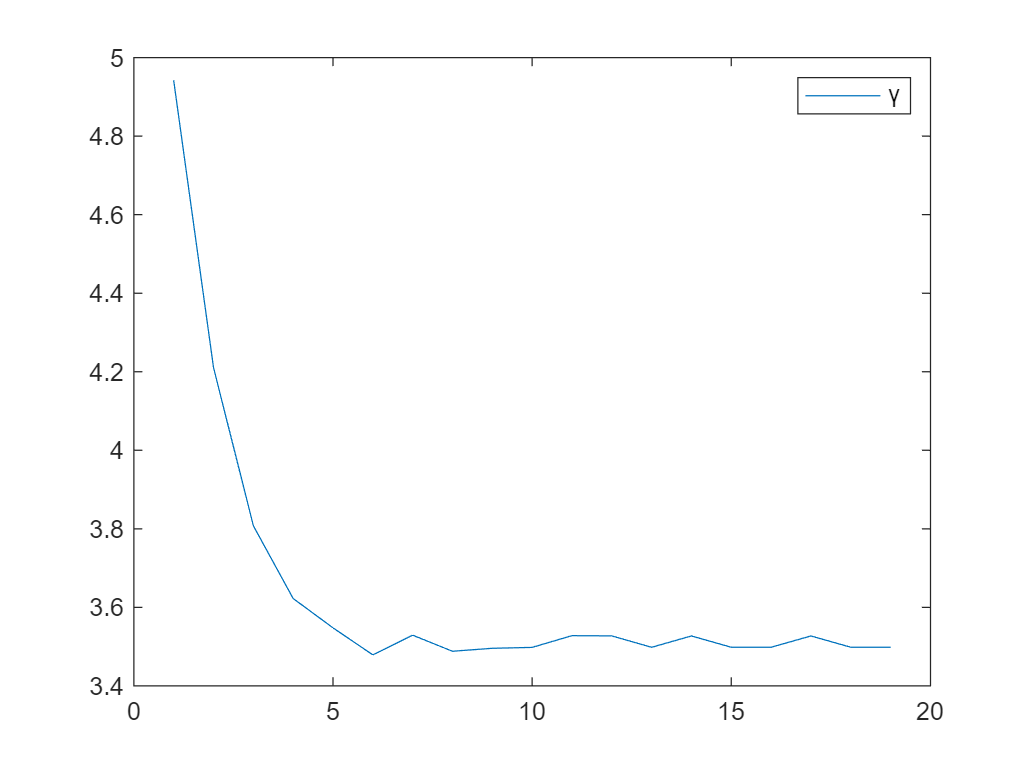

idx = 1:length(gamma);
plot(idx,gamma)
legend('\gamma')

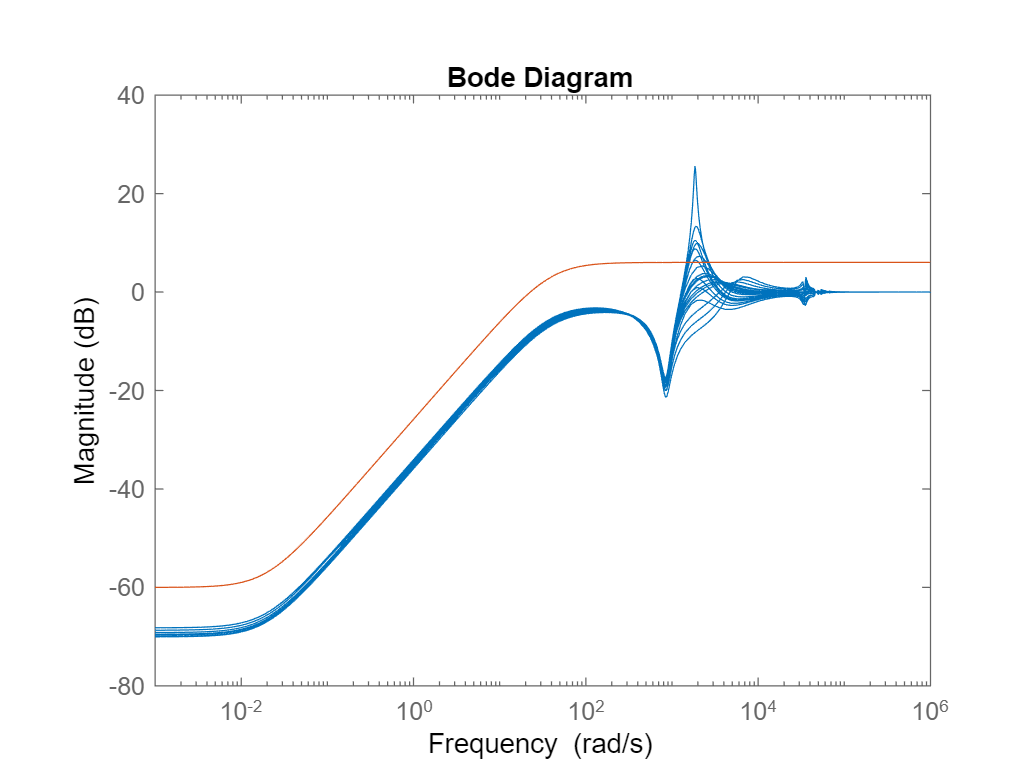

bodemag(1/(1+Gmult*K),1/Wp)

We definitely do not satisfy robust performance.  In fact, the design was not able to pull $\gamma<1$ at all.  The multiplicative uncertainty in the PZT plant is too large to handle.  However, with a better fit on the uncertainty I'm confident the answer would be different.

**Problem 3**

Get the plant model and weights.

A = [-0.0226 -36.6 -18.9 -32.1;0 -1.9 0.983 0;0.0123 -11.7 -2.63 0;0 0 1 0];
B = [0 0;-0.414 0;-77.8 22.4;0 0];
C = [0 57.3 0 0;0 0 0 57.3];
D = [0 0;0 0];
G = ss(A,B,C,D);
s = tf('s');
Wp = 0.5*(s+3)/(s+0.03)*diag([2,1]);
Wn = 2*(s+1.28)/(s+320)*eye(2);

Part 3a

I generated your plants from a known model.

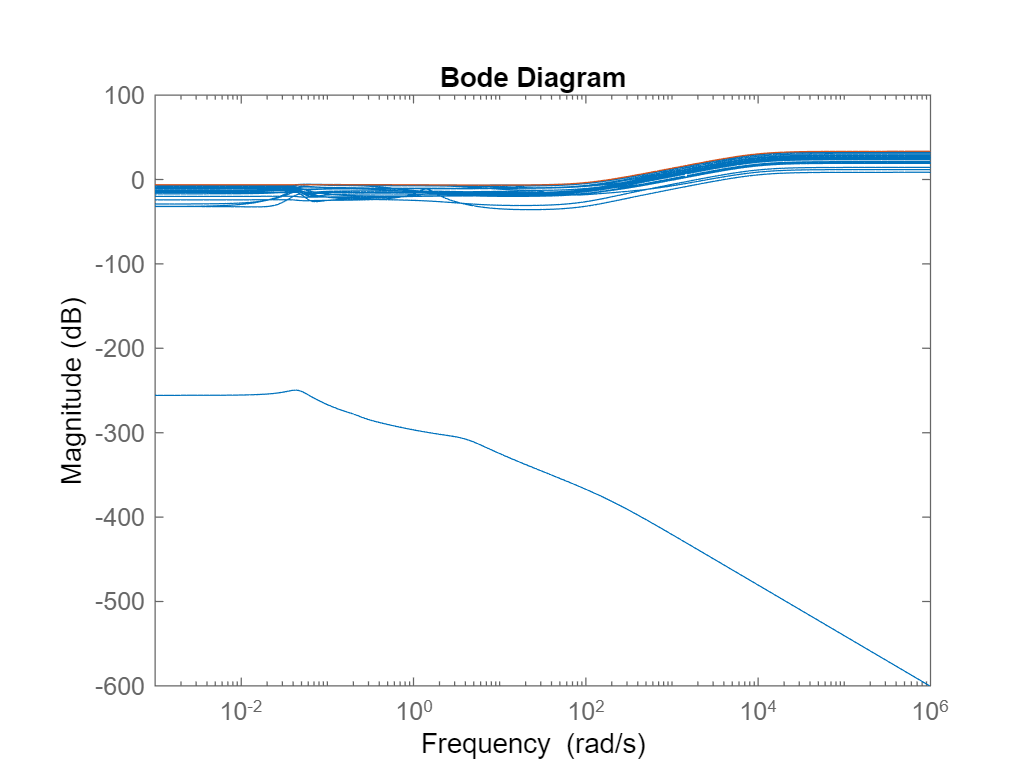

load('responses.mat');
%Wdel = 50*(s+100)/(s+10000)*eye(2);
%Gp = G*(eye(2)+Wdel*ultidyn('Delta',[2,2]));
%Gp_samples = usample(Gp,50);
[Gunc,info] = ucover(Gp_samples,G,[4,4]);
%bodemag((Gp(1,1)-G(1,1))/G(1,1),info.W1(1,1))
bodemag((Gunc(1,1)-G(1,1))/G(1,1),info.W1(1,1))

Looks good!  Now on to the synthesis.

Part 3b

First we need to build the generalized plant.

Wdel = info.W1;
systemnames = 'G Wp Wn Wdel';
inputvar = '[p{2};n{2};d{2};u{2}]';
outputvar = '[Wdel;Wp;Wn-G-d]';
input_to_G = '[u+p]';
input_to_Wp = '[G+d]';
input_to_Wn = '[n]';
input_to_Wdel = '[u]';
cleanupsysic = 'yes';
P = sysic;
[Kinf,CL,GAM] = hinfsyn(P,2,2);
GAM

GAM = 2.4201

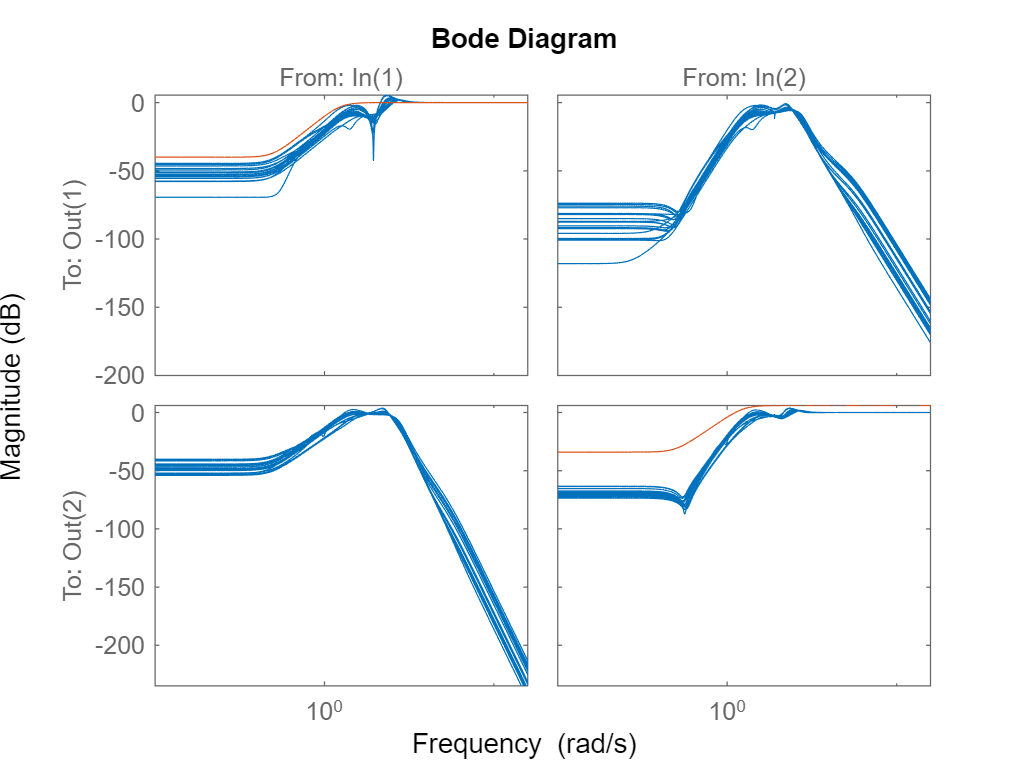


Sinf = eye(2)-feedback(Gunc*Kinf,eye(2));
bodemag(Sinf,inv(Wp))  

Some of the samples are exceeding the sensitivity bounds $\Rightarrow$ we definitely do not have robust performance.  Let's check robust stability.  The answer is yes!

[STABMARG,DESTABUNC,REPORT,INFO] = robuststab(Sinf)

STABMARG = struct with fields:
                LowerBound: 1.1293
                UpperBound: 1.1293
    DestabilizingFrequency: 64.9978


DESTABUNC = struct with fields:
    Gp_samples_InputMultDelta: [2×2 ss]


REPORT = 6×114 char array
    'System is robustly stable for the modeled uncertainty.                                                            '
    ' -- It can tolerate up to 113% of the modeled uncertainty.                                                        '
    ' -- There is a destabilizing perturbation amounting to 113% of the modeled uncertainty.                           '
    ' -- This perturbation causes an instability at the frequency 65 rad/seconds.                                      '
    ' -- Sensitivity with respect to each uncertain element is:                                                        '
    '      100% for Gp_samples_InputMultDelta. Increasing Gp_samples_InputMultDelta by 25% decreases the margin by 25%.'


INFO = struct with fields:
           Sensitivity: [1×1 struct]
             Frequency: [151×1 double]
    BadUncertainValues: [151×1 struct]
             MussvBnds: [1×2 frd]
             MussvInfo: [1×1 struct]
